# Example 9

Determine the step response for a second order system with $\omega_n =10$ rad/s and $\zeta =0.5$. Confirm your result using equation ([61](https://cpjobling.github.io/eg-150-textbook/poles_and_zeros/second_order_properties.html#equation-eq-unit5-1-2)) from the notes, and the [`tf`](https://uk.mathworks.com/help/control/ref/tf.html) and [`step`](https://uk.mathworks.com/help/control/ref/dynamicsystem.step.html) functions.

## **Solution to example 9**

Analytical solution using the symbolic math toolbox

syms s t omega_n zeta Y_s(s) y_s(t)
zeta = 0.5; omega_n = 10;
X(s) = 1/s;
H(s) = omega_n^2/(s^2 + 2*zeta*omega_n*s + omega_n^2);
Y_s(s) = H(s)*X(s)

$$Y\_s(s) = \frac{100}{s\,\left(s^{2}+10\,s+100\right)}$$

% step response 
y_s(t) = ilaplace(Y_s(s))

$$y\_s(t) = 1-{\mathrm{e}}^{-5\,t}\,\left(\cos\left(5\,\sqrt{3}\,t\right)+\frac{\sqrt{3}\,\sin\left(5\,\sqrt{3}\,t\right)}{3}\right)$$

Plot the solution

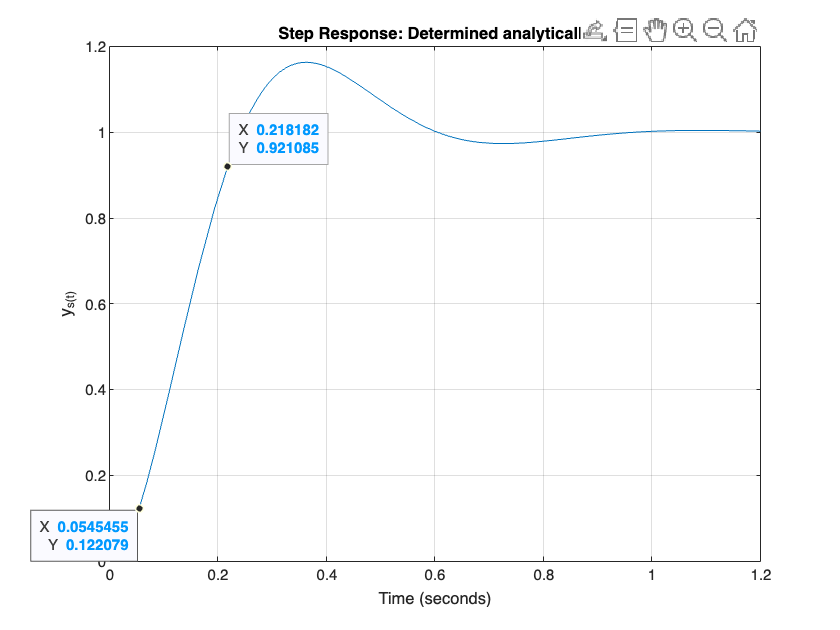

fplot(y_s(t)*heaviside(t),[0,1.2]),ylim([0,1.2]),grid
xlabel('Time (seconds)'),ylabel('y_s(t)'),...
title('Step Response: Determined analytically')

Confirming the result with ([61](https://cpjobling.github.io/eg-150-textbook/poles_and_zeros/second_order_properties.html#equation-eq-unit5-1-2)) from the notes we get:

sigma = zeta*omega_n

sigma =      5


omega = omega_n*sqrt(1 - zeta^2)

omega =    8.660254037844386


% Compute response using the formula
t = linspace(0,1.2,100);
yst = (1 - exp(-sigma*t).*(cos(omega*t)+(sigma/omega)*sin(omega*t)));

Plot the result

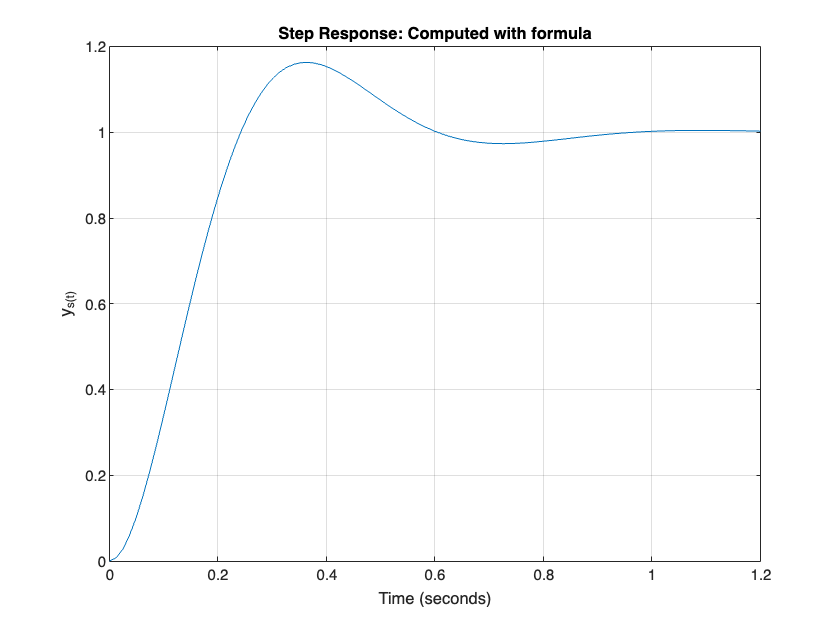

plot(t,yst),grid,...
xlabel('Time (seconds)'),ylabel('y_s(t)'),...
title('Step Response: Computed with formula')

Using the `tf` and `step` functions we get:

num = omega_n^2; den = [1 2*zeta*omega_n,omega_n^2];
Hs = tf(num,den)

Hs =
 
        100
  ----------------
  s^2 + 10 s + 100
 
Continuous-time transfer function.
Model Properties


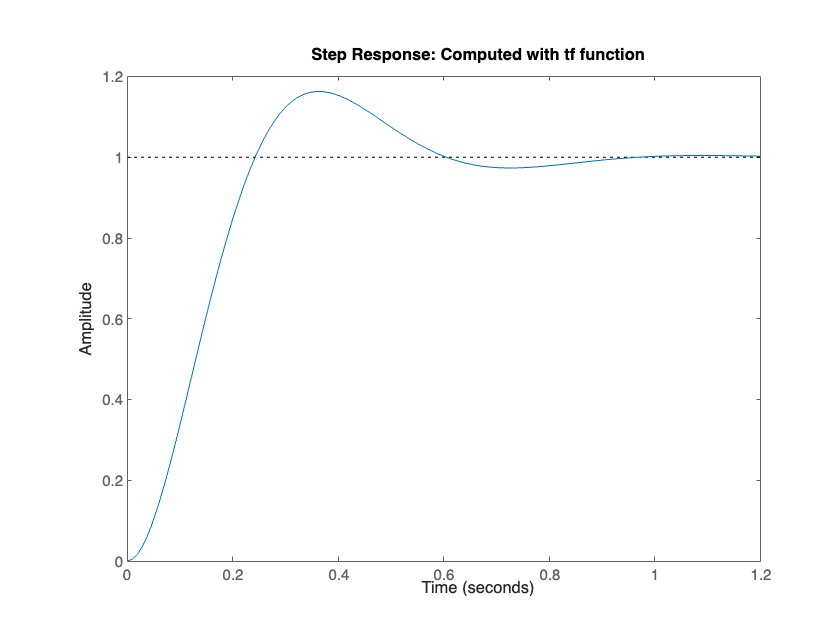

step(Hs),title('Step Response: Computed with tf function')